netflix_data = readtable('netflix.csv');

hulu_data = readtable('hulu.csv');

prime_data = readtable('prime.csv');

## Matrix Scatter Plot

%Removes any data in all the tables that is not seen as a number
number_netflix_data = netflix_data;
number_netflix_data = removevars(number_netflix_data,{'Title'});
number_netflix_data = removevars(number_netflix_data,{'Directors'});
number_netflix_data = removevars(number_netflix_data,{'Genres'});
number_netflix_data = removevars(number_netflix_data,{'Country'});
number_netflix_data = removevars(number_netflix_data,{'Language'});

number_hulu_data = hulu_data;
number_hulu_data = removevars(number_hulu_data,{'Title'});
number_hulu_data = removevars(number_hulu_data,{'Directors'});
number_hulu_data = removevars(number_hulu_data,{'Genres'});
number_hulu_data = removevars(number_hulu_data,{'Country'});
number_hulu_data = removevars(number_hulu_data,{'Language'});

number_prime_data = prime_data;
number_prime_data = removevars(number_prime_data,{'Title'});
number_prime_data = removevars(number_prime_data,{'Directors'});
number_prime_data = removevars(number_prime_data,{'Genres'});
number_prime_data = removevars(number_prime_data,{'Country'});
number_prime_data = removevars(number_prime_data,{'Language'});


%Grabs the size for the smallest data
[s1, f1] = size(number_hulu_data);

%Convert the tables to become a matrix
number_netflix_data = table2array(number_netflix_data);
number_prime_data = table2array(number_prime_data);
number_hulu_data = table2array(number_hulu_data);

%Calls the new data function to create a sheet that randomizes data
number_netflix_data = new_data(number_netflix_data, s1);

s1 = 3449

number_prime_data = new_data(number_prime_data, s1);

s1 = 12121

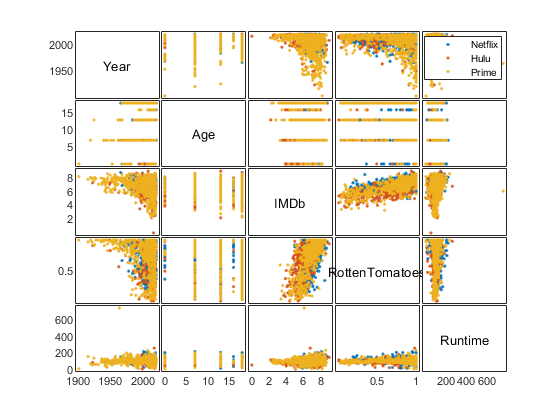



%Combine the data together all together
all_movies = [number_netflix_data;number_hulu_data];
all_movies = [all_movies;number_prime_data];


netflix_group = repmat({'Netflix'},s1,1);
hulu_group = repmat({'Hulu'},s1,1);
prime_group = repmat({'Prime'},s1,1);

movie_platform_group = [netflix_group;hulu_group];
movie_platform_group = [movie_platform_group;prime_group];


color = lines(3);

xNames = {'Year','Age','IMDb','RottenTomatoes','Runtime'};

%matrix scatter plot is created
[h,axis] = gplotmatrix(all_movies,[],movie_platform_group,color,[],[5 5],[],'variable',xNames);

%Function that takes a matrix and the max number to ouput a new matrix that
%randomize the data and cap how much it should contain
function output = new_data(matrix,max_number)
    [s1 f1] = size(matrix);
    %Adds a random number to the last column
    for i=1;s1
        matrix(i, f1+1)= rand;
    end
    
    %Sorts the last column
    c1s1 = sortrows(matrix,f1+1);
    
    %returns the data with its new size
    ctotal = [c1s1(1:max_number, 1:f1)];
    output = ctotal;
end

